%BFS
a = [1 1 2 2 2 2 3 3 3 3];  % Source nodes
s = [3 4 5 1 7 8 9 10 11 12];  % Target nodes
g = graph(a, s);  % Create graph
plot(g);  % Plot the graph
ans = bfsearch(g, 1);
disp(ans);

%DFS
a=[1 1 2 2 2 2 3 3 3 3];%dfs
s=[3 4 5 1 7 8 9 10 11 12];
g=graph(a,s);
plot(g);
ans=dfsearch(g,1);
disp(ans);

%BFS VS DFS
% Define graph edges
a = [1 1 2 2 2 2 3 3 3 3];  % Source nodes
s = [3 4 5 1 7 8 9 10 11 12];  % Target nodes

% Create graph
g = graph(a, s);
plot(g);

% Measure time and space for BFS
tic;
bfsResult = bfsearch(g, 1);  % Perform BFS starting at node 1
bfsTime = toc;
bfsSpace = whos('bfsResult');
disp(['Time for BFS: ', num2str(bfsTime), ' seconds']);
disp(['Space for BFS: ', num2str(bfsSpace.bytes / 1024), ' KB']);

% Measure time and space for DFS
tic;
dfsResult = dfsearch(g, 1);  % Perform DFS starting at node 1
dfsTime = toc;
dfsSpace = whos('dfsResult');
disp(['Time for DFS: ', num2str(dfsTime), ' seconds']);
disp(['Space for DFS: ', num2str(dfsSpace.bytes / 1024), ' KB']);

%Regression
load fisheriris;
X = meas(:,1); 
Y = meas(:,2);
m = length(X);
figure;
scatter(X, Y, 'filled');
title('Sepal Length vs Sepal Width (Original Data)');
xlabel('Sepal Length');
ylabel('Sepal Width');
hold on;
tau = 0.8;
x_test = linspace(min(X), max(X), 100)';
y_pred = zeros(size(x_test));
for i = 1:length(x_test)
 W=exp(-(X- x_test(i)).^2 / (2 * tau^2)); 
 X_design = [ones(m, 1), X];
 W_matrix = diag(W);
 theta = (X_design' * W_matrix * X_design) \ (X_design' * W_matrix * Y);
 y_pred(i) = [1, x_test(i)] * theta;
end
plot(x_test, y_pred, '-r', 'LineWidth', 2);
 legend('Original Data', 'Locally Weighted Regression Fit');
 hold off


%decision tree
load fisheriris;
treemodel= fitctree(meas, species);
view(treemodel,'Mode','graph');


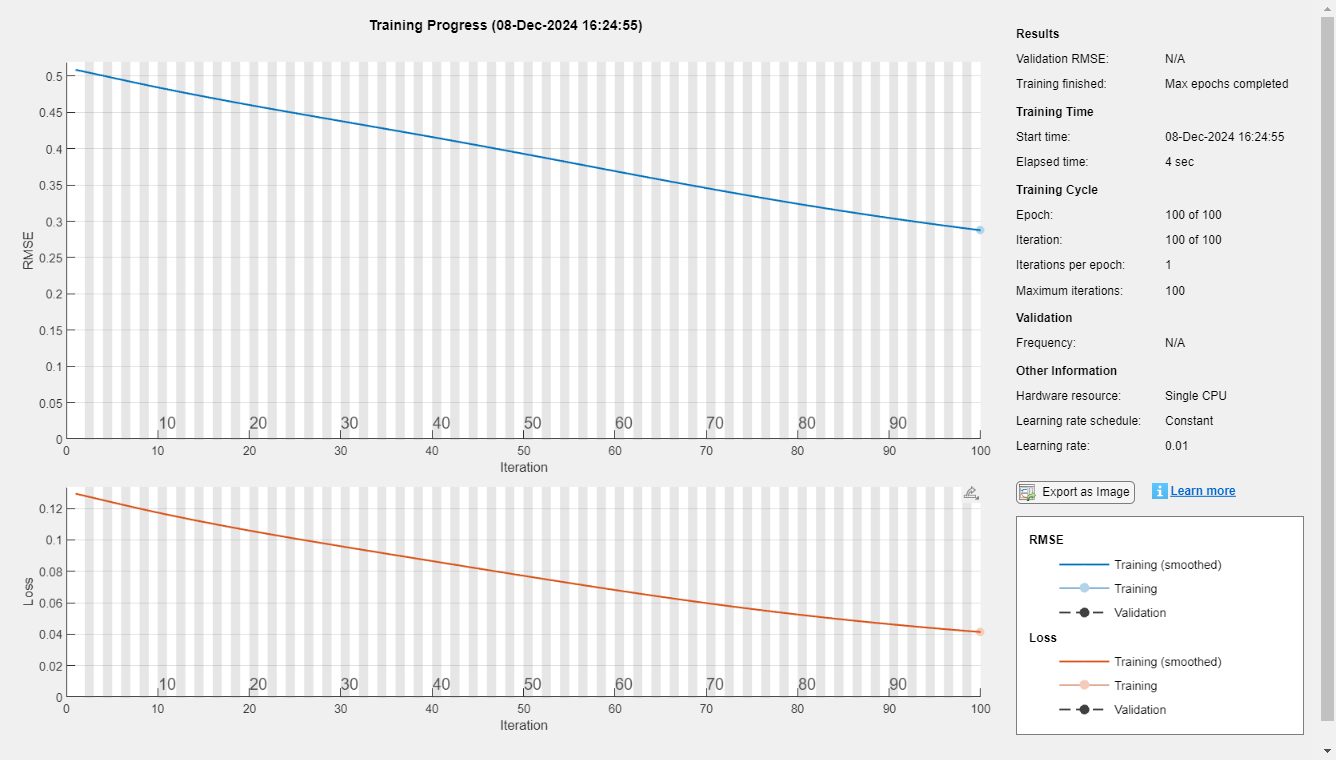

%Back Propagation

% Generate synthetic data
X = rand(100, 2); % 100 samples, 2 features
Y = double(sum(X, 2) > 1); % Target: 1 if sum > 1, else 0

% Define the neural network architecture
layers = [
    featureInputLayer(2, 'Name', 'input')             % Input layer
    fullyConnectedLayer(3, 'Name', 'hidden1')        % Hidden layer with 3 neurons
    reluLayer('Name', 'relu')                        % ReLU activation
    fullyConnectedLayer(1, 'Name', 'output')         % Output layer
    sigmoidLayer('Name', 'sigmoid')                  % Sigmoid activation
    regressionLayer('Name', 'regression')            % Regression output (can be modified for classification)
];

% Set training options
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'InitialLearnRate', 0.01, ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train the network
net = trainNetwork(X, Y, layers, options);


% Test the trained network
testInput = [0.5, 0.7];
prediction = predict(net, testInput);

fprintf('Test Input: [%.2f, %.2f], Prediction: %.4f\n', testInput(1), testInput(2), prediction);

Test Input: [0.50, 0.70], Prediction: 0.6627


%naive
load fisheriris;
nb=fitcnb(meas,species);
disp(nb);

%som
data=rand(100,2);
som=selforgmap([5 5]);
som=train(som,data);
plotsom(som.iw{1},som.layers{1}.distances);

%kmeans
load fisheriris;
X = meas;
k = 3;
[idx, C] = kmeans(X, k, 'Distance', 'sqeuclidean', 'Replicates', 5);
figure;
gscatter(X(:, 1), X(:, 2), idx, 'rgb', 'osd');
hold on;
plot(C(:, 1), C(:, 2), 'kx', 'MarkerSize', 15, 'LineWidth', 3);
title('k-Means Clustering of Iris Dataset (First Two Features)');
xlabel('Sepal Length');
ylabel('Sepal Width');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Centroids');
hold off;
disp('Cluster centroids:');
disp(C);
disp('Number of points in each cluster:');
disp(histcounts(idx, k));
figure;
silhouette(X, idx);
title('Silhouette Plot for k-Means Clustering');

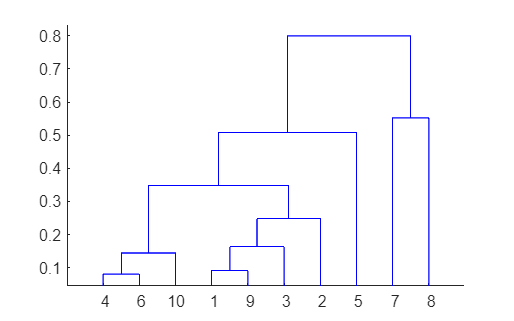

% Generate sample data
data = rand(10, 2); % 10 points in 2D space

% Perform hierarchical clustering
Z = linkage(data, 'average'); % Use 'average', 'single', or 'complete' linkage

% Plot the dendrogram
dendrogram(Z);


% Assign points to clusters (e.g., 3 clusters)
clusters = cluster(Z, 'maxclust', 3);

% Display cluster assignments
disp('Cluster Assignments:');

Cluster Assignments:


disp(clusters);

     3
     3
     3
     3
     3
     3
     1
     2
     3
     3



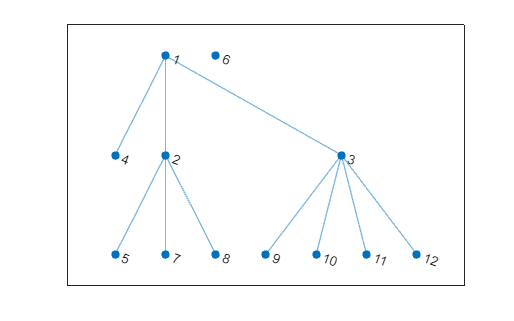

Time for BFS: 0.057583 seconds


Space for BFS: 0.085938 KB


Time for DFS: 0.024694 seconds


Space for DFS: 0.085938 KB


%dijkstra
a=[1 1 2 2 2 2 3 3 3 3];
s=[3 4 5 1 7 8 9 10 11 12];
g=graph(a,s);
plot(g);
ans=shortestpath(g,5,11);
disp(ans);